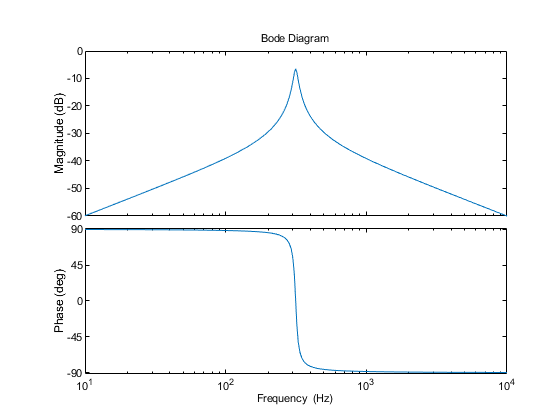

C=16e-6;
L=16e-3;
R=2.1;
wres=1/(sqrt(L*C));

s=tf('s');

T=1/(s*L+R+1/(s*C));

ops=bodeoptions;
ops.FreqUnits='Hz';
bode(T,ops)


voltage_in=15;
max_current=voltage_in/R;

max_voltage=wres*L*(voltage_in/R);